m = 0.5155

m = 0.5155

L = 1.9507

L = 1.9507

q = 9.1461

q = 9.1461

g = 9.81 

g = 9.8100

W = tf(1/m/L, [1 q/m g/L])

W =
 
         0.9944
  ---------------------
  s^2 + 17.74 s + 5.029
 
Continuous-time transfer function.



syms p
Wp = (1/m/L)/ (p^2 + q/m*p + g/L)/p

$$Wp = \frac{8957165869767353}{9007199254740992\,p\,\left(p^{2}+\frac{91461\,p}{5155}+\frac{98100}{19507}\right)}$$

wp = ilaplace(Wp)

$$wp = \frac{174727434621551754971}{883606246890091315200}-\frac{174727434621551754971\,{\mathrm{e}}^{-\frac{91461\,t}{10310}}\,\left(\cosh\left(\frac{3\,\sqrt{19507}\,\sqrt{16972293505683}\,t}{201117170}\right)+\frac{30487\,\sqrt{19507}\,\sqrt{16972293505683}\,\sinh\left(\frac{3\,\sqrt{19507}\,\sqrt{16972293505683}\,t}{201117170}\right)}{16972293505683}\right)}{883606246890091315200}$$

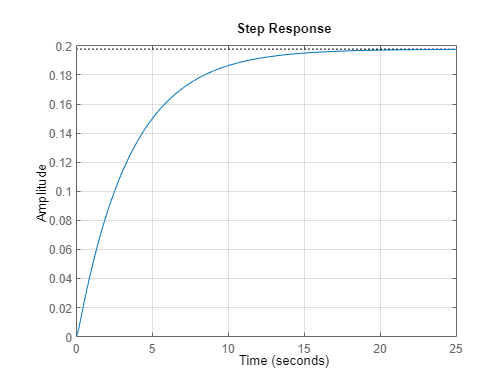

step(W)

hold on

grid on


% fplot(wp,[0,30],"red")
% syms t
% ir = sin(t*sqrt(k/m))/(sqrt(k*m))
% fplot(ir,[0,10],"red")

% syms p t
% Wp = ( Rl*Ke/L*p ) / (p+ (R+Rl)/L) 
% Wp = ( Rl*Ke/L ) / (p+ (R+Rl)/L)
% w = ilaplace(Wp)
% impulse(W)
% step(W)
% hold on
% grid on
% fplot(w,[0,0.014],"red")


% per =  Ke*Rl *(L * ( exp( -t *(Rl + R)/L ) - 1 ) + t*(Rl+R) ) / ((Rl+R)^2)
% fplot(per,[0,0.014],"red")

% h = (Ke* L* M exp(-(M* t) / (L - (R t)\/L)) / (M^2 + 2 M R + R^2) - (K L M)\/(M^2 + 2 M R + R^2) + (K M t)\/(M + R)
% syms s 
% b = Km/J/R
% a = Ke*Km/J/R
% teta = 1/Km - 1/Km*exp(-Km*Ke/J/R*t)
% pereh = t/Km+J*R/Km^2/Ke*exp(-Km*Ke/J/R*t)
% step(W)
% hold on
% grid on
% p = [1 Km*Ke/J/R 0]
% roots(p)
% fplot(per,[0,0.1],"red")
% 

% % АЧХ
% syms w
% 
% Wjw = ( 1/m/L ) / ( (1i*w)^2 + q/m*1i*w + g/L)
% A1=sqrt(real(Wjw)^2+imag(Wjw)^2)
% 
% % fplot(A1,[0,10])
% % grid on
% % xlabel("Frequency")
% % ylabel("Amplitude")
% % title("АЧХ")
% % legend("A(ω)")
% % фчх
% F=atan2(imag(Wjw), real(Wjw))
% 
% fplot(F,[0,100])
% grid on
% xlabel("Frequency")
% ylabel("Phase")
% title("ФЧХ")
% legend("φ(ω)")
% bode(W)
% grid on